Todd Blacklaw MATLAB Final Project H00368671

I have included discussion notes throughout the file as I thought it would be easier to follow than just pasting all the information at the start.

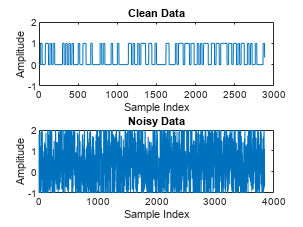

clc;
clear;

% 1A. Import 
load('digitalData.mat');

% Plot the clean and noisy data
figure;
subplot(2,1,1);
plot(cleanData);
title('Clean Data');
ylabel('Amplitude');
xlabel('Sample Index');
ylim([-1 2]);

subplot(2,1,2);
plot(noisyData);
title('Noisy Data');
ylabel('Amplitude');
xlabel('Sample Index');
ylim([-1 2]);


% 1B. Sampling function that accepts a threshold parameter
sampledDataThreshold = @(x, threshold) reshape((x(1:20:end) > threshold), 1, []);

% 1C. Call the sampling function on the clean and noisy data using a fixed threshold
fixedThreshold = 0.5;
cleanSampled = sampledDataThreshold(cleanData, fixedThreshold);
noisySampled = sampledDataThreshold(noisyData, fixedThreshold);

cleanMsg = char(bin2dec(reshape(char(cleanSampled+'0'), 8, []).'));
noisyMsg = char(bin2dec(reshape(char(noisySampled+'0'), 8, []).'));

disp('Clean Data Message:');

Clean Data Message:


disp(cleanMsg);

M
A
T
L
A
B
 
i
s
 
a
w
e
s
o
m
e
!



disp('Noisy Data Message:');

Noisy Data Message:


disp(noisyMsg);

²
¢
t
ð


é
T
A

j
 
é
x

@
õ


ç
P
(
m
«


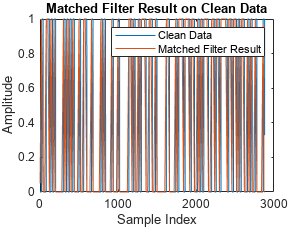


% 1D. Matched filter design and convolution with clean data
matchedFilter = [zeros(1, 20) ones(1, 20) zeros(1, 20)];
matchedFilterResult = conv(cleanData, fliplr(matchedFilter), 'same');
matchedFilterResult = matchedFilterResult / max(matchedFilterResult);
matchedFilterResult = circshift(matchedFilterResult, [-10 0]);

% Plot matched filter result on top of clean data
figure;
plot(cleanData);
hold on;
plot(matchedFilterResult);
title('Matched Filter Result on Clean Data');
legend('Clean Data', 'Matched Filter Result');
ylabel('Amplitude');
xlabel('Sample Index');
hold off;


% 1E. Call sampling function on the matched filter result using fixed threshold
cleanMatchedSampled = sampledDataThreshold(matchedFilterResult, fixedThreshold);
cleanMatchedMsg = char(bin2dec(reshape(char(cleanMatchedSampled+'0'), 8, []).'));

disp('Matched Filter Result (Clean Data):');

Matched Filter Result (Clean Data):


disp(cleanMatchedMsg);

M
A
T
L
A
B
 
i
s
 
a
w
e
s
o
m
e
!


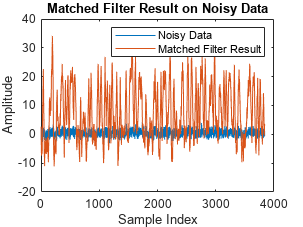


% 1F. Matched filter procedure for noisy data
noisyMatchedFilterResult = conv(noisyData, fliplr(matchedFilter), 'same');
noisyMatchedFilterResult = circshift(noisyMatchedFilterResult, [-10 0]);

% Get sampled values from the matched filter result
sampleIndices = 1:20:length(noisyMatchedFilterResult);
sampledValues = noisyMatchedFilterResult(sampleIndices);

% Compute dynamic threshold for noisy data
dynamicThreshold = (max(sampledValues) + min(sampledValues)) / 2;

% Call sampling function on the matched filter result for noisy data using dynamic threshold
noisyMatchedSampled = sampledDataThreshold(noisyMatchedFilterResult, dynamicThreshold);
noisyMatchedMsg = char(bin2dec(reshape(char(noisyMatchedSampled+'0'), 8, []).'));

% Plot matched filter result on top of noisy data
figure;
plot(noisyData);
hold on;
plot(noisyMatchedFilterResult);
title('Matched Filter Result on Noisy Data');
legend('Noisy Data', 'Matched Filter Result');
ylabel('Amplitude');
xlabel('Sample Index');
hold off;


disp('Matched Filter Result (Noisy Data):');

Matched Filter Result (Noisy Data):


disp(noisyMatchedMsg);

 
b
u
t
 
P
Y
T
H
O
N
 
i
s
 
b
e
t
t
e
r
 
;
)


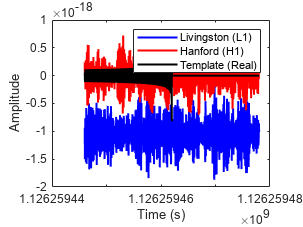


% 2A: Import LIGO data and load matched filter template

% Load LIGO data
dataL1 = csvread('DataL1.csv');
dataH1 = csvread('DataH1.csv');

% Extract strain and time columns
strainL1 = dataL1(:, 1);
time = dataL1(:, 2);

strainH1 = dataH1(:, 1);

% Load matched filter template
templateData = csvread('DataTemplate.csv');
templateReal = templateData(:, 1);
templateImag = templateData(:, 2);

% Combine real and imaginary parts to form a complex array
template = complex(templateReal, templateImag);

% Plot LIGO strain data and matched filter template
figure;
plot(time, strainL1, 'b', 'LineWidth', 1.5, 'DisplayName', 'Livingston (L1)');
hold on;
plot(time, strainH1, 'r', 'LineWidth', 1.5, 'DisplayName', 'Hanford (H1)');
plot(time, real(template), 'k', 'LineWidth', 1.5, 'DisplayName', 'Template (Real)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('show');

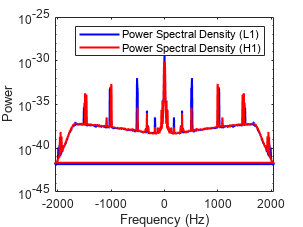


% 2B: Define the sampling rate and calculate the step size in the frequency domain

% Define the sampling rate
fs = 4096;

% Generate a vector of frequencies using fftfreq.m function
totalPoints = length(time);
dt = 1/fs;
freqVector = fftfreq(totalPoints, dt);

% Calculate the step size in the frequency domain
df = abs(freqVector(2) - freqVector(1));

% 2C: Prepare the Fourier transforms of the template and data

% Create a Blackman window
windowLength = length(template);
blackmanWindow = blackman(windowLength);

% Apply Blackman window to data and template
windowedStrainL1 = strainL1 .* blackmanWindow;
windowedStrainH1 = strainH1 .* blackmanWindow;
windowedTemplate = template .* blackmanWindow;

% Compute Fourier transforms
strainL1FFT = fft(windowedStrainL1);
strainH1FFT = fft(windowedStrainH1);
templateFFT = fft(windowedTemplate);

% 2D: Calculate the power spectral density and apply the matched filter template

% Calculate power spectral density
powervecL1 = abs(strainL1FFT).^2;
powervecH1 = abs(strainH1FFT).^2;

% Calculate moving average of the power spectral density
windowSize = 200;
powervecL1 = movmean(powervecL1, windowSize);
powervecH1 = movmean(powervecH1, windowSize);

% Plot power spectral density
figure;
semilogy(freqVector, powervecL1, 'b', 'LineWidth', 1.5, 'DisplayName', 'Power Spectral Density (L1)');
hold on;
semilogy(freqVector, powervecH1, 'r', 'LineWidth', 1.5, 'DisplayName', 'Power Spectral Density (H1)');
xlabel('Frequency (Hz)');
ylabel('Power');
legend('show');

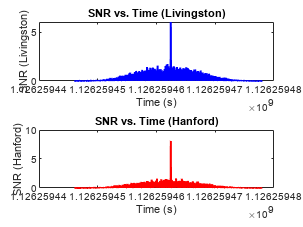


% Discussion on Noise:
% The power spectral density plot reveals several peaks, which could be due to instrumental noise or environmental factors.
% Common sources of noise in LIGO include seismic activity, thermal noise, and instrumental noise from lasers or mirrors.

% 2E: Apply the matched filter template

% Apply convolution theorem
matchedFilterResultL1 = ifft(strainL1FFT .* conj(templateFFT) ./ powervecL1) * 2 * fs;
matchedFilterResultH1 = ifft(strainH1FFT .* conj(templateFFT) ./ powervecH1) * 2 * fs;

% 2F: Normalize the matched filter output and calculate SNR

% Normalize the matched filter output
sigmasqL1 = sum(templateFFT .* conj(templateFFT) ./ powervecL1) * df;
sigmaL1 = sqrt(abs(sigmasqL1));
SNR_complexL1 = matchedFilterResultL1 ./ sigmaL1;

sigmasqH1 = sum(templateFFT .* conj(templateFFT) ./ powervecH1) * df;
sigmaH1 = sqrt(abs(sigmasqH1));
SNR_complexH1 = matchedFilterResultH1 ./ sigmaH1;

% Shift the SNR vector by half the template length
peaksample = round(length(template) / 2);
SNR_complexL1 = circshift(SNR_complexL1, peaksample);
SNR_complexH1 = circshift(SNR_complexH1, peaksample);

% Calculate SNR
SNR_L1 = abs(SNR_complexL1);
SNR_H1 = abs(SNR_complexH1);

% Find the time and SNR value at the maximum
indmax_L1 = find(SNR_L1 == max(SNR_L1));
indmax_H1 = find(SNR_H1 == max(SNR_H1));

timemax_L1 = time(indmax_L1);
timemax_H1 = time(indmax_H1);

SNRmax_L1 = SNR_L1(indmax_L1);
SNRmax_H1 = SNR_H1(indmax_H1);

% Calculate the "effective distance" and optimal horizon distance
d_eff_L1 = sigmaL1 / SNRmax_L1;
d_eff_H1 = sigmaH1 / SNRmax_H1;
horizon_L1 = sigmaL1 / 8;
horizon_H1 = sigmaH1 / 8;

% Extract time offset and phase at peak
phase_L1 = angle(SNR_complexL1(indmax_L1));
offset_L1 = (indmax_L1 - peaksample);

phase_H1 = angle(SNR_complexH1(indmax_H1));
offset_H1 = (indmax_H1 - peaksample);

% Apply time offset, phase, and d_eff to template
template_phaseshifted_L1 = real(template .* exp(1j * phase_L1));
template_rolled_L1 = circshift(template_phaseshifted_L1, offset_L1) / d_eff_L1;

template_phaseshifted_H1 = real(template .* exp(1j * phase_H1));
template_rolled_H1 = circshift(template_phaseshifted_H1, offset_H1) / d_eff_H1;

% Plot SNR vs. time for Livingston (L1)
figure;
subplot(2, 1, 1);
plot(time, SNR_L1, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('SNR (Livingston)');
title('SNR vs. Time (Livingston)');

% Plot SNR vs. time for Hanford (H1)
subplot(2, 1, 2);
plot(time, SNR_H1, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('SNR (Hanford)');
title('SNR vs. Time (Hanford)');

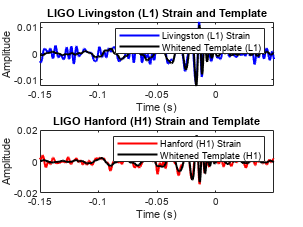


% 2G: Post-process the data and template with whitening and bandpass filters

% Whitening filter function
whitenFilter = @(data, powervec) ifft(fft(data) ./ sqrt(powervec));

% Apply whitening filter to rolled template and strain data
whitenedTemplate_L1 = whitenFilter(template_rolled_L1, powervecL1);
whitenedStrainL1 = whitenFilter(strainL1, powervecL1);

whitenedTemplate_H1 = whitenFilter(template_rolled_H1, powervecH1);
whitenedStrainH1 = whitenFilter(strainH1, powervecH1);

% Bandpass filter function
bandpassFilter = @(data, fband, fs) bandpass(data, fband, fs);

% Apply bandpass filter to whitened template and strain data
fband = [43, 300];
bandpassTemplate_L1 = bandpassFilter(whitenedTemplate_L1, fband, fs);
bandpassStrainL1 = bandpassFilter(whitenedStrainL1, fband, fs);

bandpassTemplate_H1 = bandpassFilter(whitenedTemplate_H1, fband, fs);
bandpassStrainH1 = bandpassFilter(whitenedStrainH1, fband, fs);

% 2H: Plot the results

% Shift the time vector so that the event is at t=0
timeShifted_L1 = time - timemax_L1;
timeShifted_H1 = time - timemax_H1;

% Plot results
figure;

subplot(2, 1, 1);
plot(timeShifted_L1, real(bandpassStrainL1), 'b', 'LineWidth', 1.5, 'DisplayName', 'Livingston (L1) Strain');
hold on;
plot(timeShifted_L1, real(bandpassTemplate_L1), 'k', 'LineWidth', 1.5, 'DisplayName', 'Whitened Template (L1)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('show');
xlim([-0.15, 0.05]);

title('LIGO Livingston (L1) Strain and Template');

subplot(2, 1, 2);
plot(timeShifted_H1, real(bandpassStrainH1), 'r', 'LineWidth', 1.5, 'DisplayName', 'Hanford (H1) Strain');
hold on;
plot(timeShifted_H1, real(bandpassTemplate_H1), 'k', 'LineWidth', 1.5, 'DisplayName', 'Whitened Template (H1)');
xlabel('Time (s)');
ylabel('Amplitude');
legend('show');
xlim([-0.15, 0.05]);

title('LIGO Hanford (H1) Strain and Template');


% Discussion on Final Results:
% The final results show the strain data from the Livingston and Hanford observatories overlaid with the matched template. 
% After applying whitening and bandpass filtering, the event becomes more visually distinguishable. 
% The agreement between the template and strain data clearly shows the gravitational wave signal detected by both observatories.


function f = fftfreq(npts,dt)
% Function to get the frequency axis corresponding to the DFFT of a signal
% Input is the number of points in the signal, and the step in the time
% domain
fmin = -1/(2*dt); % f min = -fs/2
df = 1/(npts*dt); % df = fs/N
f = mod(linspace(0,2*(-fmin)-df,npts)-fmin,-2*fmin)+fmin;
end

